# Exemple : classification d'une image

Ce script montre comment utiliser le réseau préentraîné sur une image. 

Le réseau neuronal plantnetcorn livré est directemennt utilisable  sans relancer la fonctione d'entraînement du réseau

## Pour pouvoir réutiliser un réseau neuronal entraîné 

- Enregistrer le réseau dans le script où le réseau est entraîné (ex : `save plantnetcorn)`

- Cela génère un fichier `plantnetcorn.mat`

- Dans un script il suffit ensuite de charger le réseau (load) pour pouvoir l'utiliser.

% chargement du cnn pré-entraine
load plantnetcorn.mat
net = plantnetcorn

net =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'new_out'}


% utilisation du réseau sur une image
I = imread("img/Corn_(maize)___Common_rust_/RS_Rust 1564.JPG")

I = 256×256×3 uint8 array
I(:,:,1) =

     6     6     4     4     3     2     2     0     2     0   138   116    93    98    88   104   111   100    96   104   109   106   105   108   115   103   100   110   119   117   115   119   108   114   120   124   120   114   115   120   123   123   119   114   114   121   125   125   136   125   113   111   119   121   117   110   112   110   131   159   158   140   126   117   111   114   114   114   119   112   111   120   124   128   132   134   131   130   135   138   118   114   112   113   112   110   111   116   107   108   102    95    96   104   107   106   117   106   103    99    96   104   109   101    95   103   102    92    95   107   112   101    98    98   102   103    96    90    94   102    92    95    93    89    87    87    85    83   107   110   113   115   108    96    92    96   105    99     0     9     6     0     0     9     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3  

% mise à la taille de l'image au format d'image attendu par le réseau neuronal
inputSize = net.Layers(1).InputSize;
I = imresize(I,inputSize(1:2));

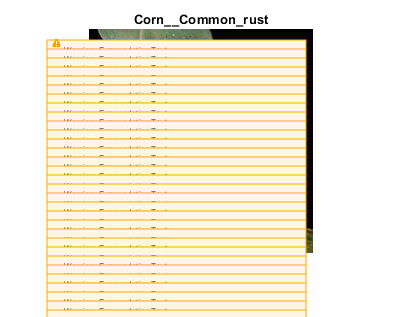

% classification et affichage de l'image avec son label
label = classify(net,I);
figure
imshow(I)
title(string(label))